%%
clear
close all
clc

T_c = 20;		    % C, Temperature (20 C = 68 F = 293.15 K)
T = T_c + 273.15;   % K
P_g = 101.325;		% kPa, Total Pressure (101.325 kPa = 1 atm = 14.696 psi)
phi = 0.50;         % Relative humidity
V_g = 1;
y0 = T;             % K, Initial temperature

%% (a) Analytical
% t = 0 : 0.01 : 10;
% y_a = exp(-a*t + t.^3./3);

% figure
% plot(t, y_a)
% hold on; grid on

%% (b) Euler's Method
step = 0.5;
y(1) = y0;                        % t = 0
y(2) = y(1) + step * my_fun(0.5, y(1), phi, V_g, P_g); % t = 0.5

P_s = 0.0234

y(3) = y(2) + step * my_fun(1.0, y(2), phi, V_g, P_g); % t = 1

P_s = 0.0234

y(4) = y(3) + step * my_fun(1.5, y(3), phi, V_g, P_g); % t = 1.5

P_s = 0.0234

y(5) = y(4) + step * my_fun(2.0, y(4), phi, V_g, P_g); % t = 2

P_s = 0.0234

figure
plot(0:step:2, y, '--or') % red circles
grid on; hold on

%% As a loop
step= 0.25;
y = zeros(8,1);
y(1) = y0;
for i = 1 : 2/step
    y(i+1) = y(i) + step * my_fun(i*step, y(i), phi, V_g, P_g);
end

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

plot(0:step:2, y, '--*k') % black stars

%% (c) Heun's Method
step = 0.5;
y_c = zeros(5,1);
y_c(1) = y0;
for i = 1 : 2/step
    int = y_c(i) + step * my_fun(i*step, y_c(i), phi, V_g, P_g);
    y_c(i+1)   = y_c(i) + (step/2) * (my_fun(i*step-0.5, y_c(i), phi, V_g, P_g) + my_fun(i*step, int, phi, V_g, P_g));
end

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

P_s = 0.0234

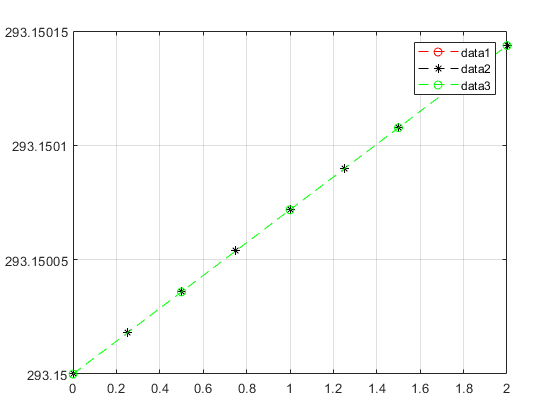

plot(0:step:2, y_c, '--og') % green circles

%%
legend

shg


function q = my_fun(t, T, phi, V_g, P_g)

R_a = 287.058;      % J/(kg*K), Specific Gas Constant, dry air
R_v = 461.495;      % J/(kg*K), Specific Gas Constant, water vapor

if T < 647.096 && T > 273.15
    teta = T - 0.23855557567849 / (T - 650.17534844798);
    a = teta ^ 2 + 1167.0521452767 * teta - 724213.16703206;
    B = -17.073846940092 * teta ^ 2 + 12020.82470247 * teta - 3232555.0322333;
    C = 14.91510861353 * teta ^ 2 - 4823.2657361591 * teta + 405113.40542057;
    p4_T = (2 * C / (-B + (B ^ 2 - 4 * a * C) ^ 0.5)) ^ 4;
    P_s = p4_T * 10;  % bar to MPa
else
    error('Temperature out of valid range.')
end

q = ((phi * P_s) * V_g / (R_v * T))/(P_g * (V_g - (((phi * P_s) * V_g / (R_v * T)) * R_v * T / P_g)) / (R_a * T));

end